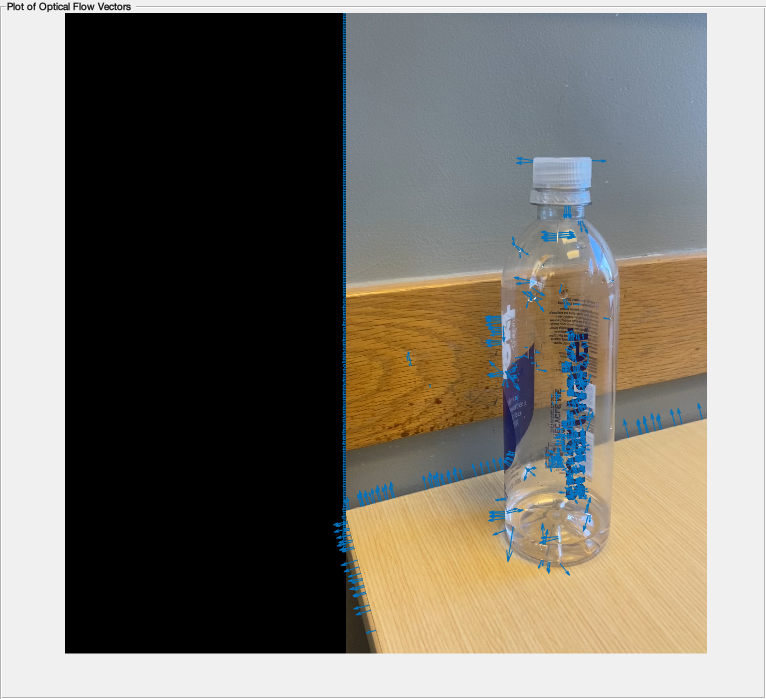

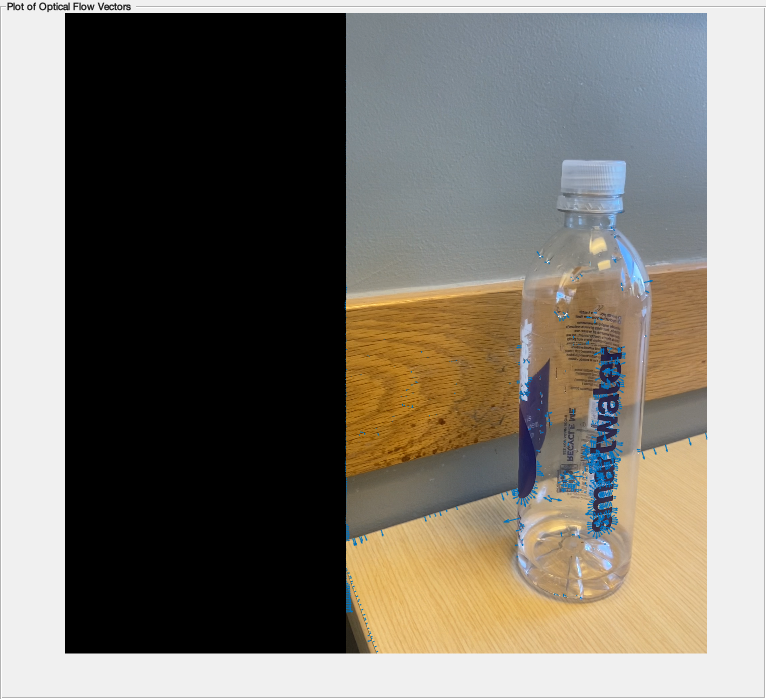

% Treating every 11th frame as a reference frame
vidReader = VideoReader('./IMG_1667.mov','CurrentTime',1);
opticFlow = opticalFlowLK('NoiseThreshold',0.009);

h = figure;
movegui(h);
hViewPanel = uipanel(h,'Position',[0 0 1 1],'Title','Plot of Optical Flow Vectors');
hPlot = axes(hViewPanel);

freq=11;
for v = 1:freq:vidReader.NumFrames
    frameRGB = read(vidReader, v);
    frameGray = rgb2gray(frameRGB);
    
    flow = estimateFlow(opticFlow,frameGray);
    
    imshow(frameRGB)
    hold on
    plot(flow,'DecimationFactor',[5 5],'ScaleFactor',10,'Parent',hPlot);
    hold off
    pause(10^-3)
end